# Informe Laboratorio: Análisis Numérico

# Práctica No. 0

**Juan Pablo Jiménez Gómez **

**Código: 2173051**

**Grupo: B2**

*Escuela de ingeniería de sistemas e informática*

*Universidad Industrial de Santander*

31 de Octubre de 2020

#### **1 Introducción**

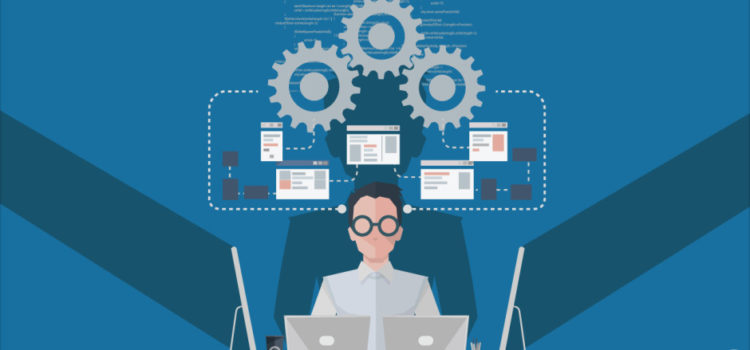

Para el siguiente laboratorio se llevarán a cabo algunos ejercicios referentes a temáticas tales como la implementación del punto flotante y de igual manera la implementación de la ecuación cuadrática en el entorno de desarrollo de Matlab. Cabe resaltar que la aritmética del punto flotante, se usa para representar formulas con respecto a números reales de tal manera que funcione como una aproximación ya sea para redondear un numero de acuerdo a un rango u precisión establecida, además de escalar respecto al exponente o base que use la función para el ejercicio. Al ser implementado en los entornos de desarrollo, suele tener tiempos de procesamiento veloz cuyo resultado se verá representado por un número fijo de dígitos significativos. También hay que tener en cuenta los conceptos básicos para la resolución de la ecuación cuadrática donde se tiene a x como la variable principal, y tanto a,b,c serán las constantes donde a tiene el nombre de coeficiente cuadrático, b viene siendo el coeficiente lineal, y c es el termino independiente. En el laboratorio se tendrá que programar la función de tal manera que se evalué la igualdad al racionalizar la función, sino también apreciar y las diferentes soluciones, para los casos presentados.

#### **2 Desarrollo**

- (0.5 points )Use three-digit rounding arithmetic to compute the following sums:

## 
$$a\ldotp \sum_{k=1}^6 \frac{1}{3^k }$$


s1=1./3.^(1:6)

s1 =     0.3333    0.1111    0.0370    0.0123    0.0041    0.0014


suma1= round (sum(s1),3)

suma1 = 0.4990

Calculo para el %error relativo

Teo_1 = sum(s1);
Exp_1 = suma1;
ErrRe_1 = abs((Teo_1-Exp_1)/Teo_1)*100

ErrRe_1 = 0.0629

## 
$$b\ldotp \sum_{k=1}^6 \frac{1}{3^{7-k} }$$


s2=1./3.^7-(1:6)

s2 =    -0.9995   -1.9995   -2.9995   -3.9995   -4.9995   -5.9995


suma1= round (sum(s1),3)

suma1 = 0.4990

Calculo para el %error relativo

Teo_2 = sum(s2);
Exp_2 = suma1;
ErrRe_2 = abs((Teo_2-Exp_2)/Teo_2)*100

ErrRe_2 = 102.3765

**Análisis: **El primer punto el cual está dividido en a y b, nos muestra la función que cumplen las sumatorias de una función. Lo primero que se hizo fue digitar los valores que se iban a calcular para la sumatoria, haciendo enfásis en la respectiva operación que pidiera en cada ejercicio, de tal manera que al llevar a cabo este proceso se redondee el numero que se está calculando. A demás de esto, nosotros tenemos muy en cuenta el calculo del error relativo porcentual donde se digitan los valores de las sumas y se resta el valor teórico menos el experimental multiplicado por cien, para determinar dicho error de redondeo que hay en la suma. 

- (1.0 points) Improving the Quadratic Formula. Assume that  $a\not= 0$ and $\textrm{b2}-4\textrm{ac}>0$ and consider the equation ${\textrm{ax}}^2 +\textrm{bx}+c=0$ .The roots can be computed with the quadratic formulas


$$\textrm{x1}=\frac{-b+\sqrt{b^2 -4\textrm{ac}}}{2a},\textrm{x2}=\frac{-b-\sqrt{b^2 -4\textrm{ac}}}{2a}$$


**Show that these roots can be calculated with the equivalent formulas**


$$\textrm{x1}=\frac{-2c}{b+\sqrt{b^2 -4\textrm{ac}}},\textrm{x2}=\frac{-2c}{b-\sqrt{b^2 -4\textrm{ac}}}$$


Hint. Rationalize the numerators in (1). Remark. In the cases when $\left|b\right|\approx \sqrt{b^2 -4\textrm{ac}}$, one must proceed with caution to avoid loss of precision due to a catastrophic cancellation. If b > 0, then $x_1$ should be computed with formula (2), and $x_2$ should be computed using (1). However, if b < 0, then $x_1$ should be computed using (1), and $x_2$ should be computed using (2).

Primero demostramos para x1:


$$\textrm{x1}=\frac{-b+\sqrt{b^2 -4\textrm{ac}}}{2a}*\frac{-b-\sqrt{b^2 -4\textrm{ac}}}{-b-\sqrt{b^2 -4\textrm{ac}}}\;=\;\frac{b^2 -\left(b^2 -4\textrm{ac}\right)}{2a\left(-b-\sqrt{b^2 -4\textrm{ac}}\right)}\;=\frac{4\textrm{ac}}{\left(2a\left(-b-\sqrt{b^2 -4\textrm{ac}}\right)\right)}=\frac{-2c}{b+\sqrt{b^2 -4\textrm{ac}}}$$
 

**Ahora demostramos para x2:**


$$\textrm{x2}=\frac{-b-\sqrt{b^2 -4\textrm{ac}}}{2a}*\frac{-b+\sqrt{b^2 -4\textrm{ac}}}{-b+\sqrt{b^2 -4\textrm{ac}}}\;=\;\frac{b^2 -\left(b^2 -4\textrm{ac}\right)}{2a\left(-b+\sqrt{b^2 -4\textrm{ac}}\right)}\;=\frac{4\textrm{ac}}{\left(2a\left(-b+\sqrt{b^2 -4\textrm{ac}}\right)\right)}=\frac{-2c}{b-\sqrt{b^2 -4\textrm{ac}}}$$


**Análisis:** Para el segundo punto el procedimiento fue un poco más simple, debido a que se nos pedia demostrar como al hacer el procedimiento de racionalizar la función cuadratica, podiamos tener uno de los dos resultados que se nos presenta en el enunciado para cuando a es diferente de cero y tanto el valor b como el c es mayor a cero. De tal manera que primero se racionalizara x1 y luego se hiciera lo mismo con x2, probando así que la demostración echa es la correcta y se cumplen los resultados propuestos.

## Implementing

- (2.0 points) Create a Matlab function called *foating_point_function_name_lastname() *to de-termine the oating point format to stored decimal numbers in a computer with 32 bits of precision. Use the following numbers to test your function:

**a) **${1612\ldotp 078125}_{10}$

**b) **${6317\ldotp 91361}_{10}$

**c) **${-962\ldotp 0153}_{10}$

floating_point(2.86667);

Machine Number: 01000000001101110111011110000101(2)

floating_point(6317.9136);

Machine Number: 01000101110001010110111101001111(2)

floating_point(-962.0153);

Machine Number: 11000100011100001000000011111011(2)

**Análisis: **El tercer punto está dividido en dos partes,  la primera parte que es donde se definen las variablesA,B,C que son los valores de prueba que tienen las funciones del punto flotante, y en la segunda parte que es donde se programara el código. Cabe resaltar que esto se hizo para el adecuado cumplimiento de las normas de calificación establecidas por el auxiliar. El proposito de este ejercicio es el de crear una función denominada como  *foating_point_function_name_lastname(). *Que permita determinar números decimales almacenados en una computadora con 32 bits de precisión haciendo uso del formato de punto flotante para los valores sugeridos*. *

- (1.5 points) Use the results obtained in Improving the Quadratic Formula to construct a Matlab program that will accurately compute the roots of a quadratic equation in all situations, including the troublesome ones when $\left|b\right|\approx \sqrt{b^2 -4\textrm{ac}}$

a = 1;
b = -1000.001;
c = 1;
[x1a,x2a]=Improving_the_Quadratic_Formula(a,b,c)

x1a = 1000

x2a = 1.0000e-03


a = 1;
b = -10000.0001;
c = 1;
[x1b,x2b]=Improving_the_Quadratic_Formula(a,b,c)

x1b = 10000

x2b = 1.0000e-04


a = 1;
b = -100000.00001;
c = 1;
[x1c,x2c]=Improving_the_Quadratic_Formula(a,b,c)

x1c = 100000

x2c = 1.0000e-05


a = 1;
b = -1000000.000001;
c = 1;
[x1d,x2d]=Improving_the_Quadratic_Formula(a,b,c)

x1d = 1000000

x2d = 1.0000e-06

**Análisis: **En el cuarto punto se nos pidio hacer uso de los resultados obtenidos anteriormente en otros puntos donde calculamos los dos respectivos casos de la función cuadrática, y donde posterior a esto debemos programar una función que nos permita calcular la precisión de todas las raíces de una ecuación cuadrática en todas los tipos de casos presentados, tales como:  $\left|b\right|\approx \sqrt{b^2 -4\textrm{ac}}$. Bien, dicho lo anterior, sucedera algo similar a lo que se dijo en el tercer punto, donde en primera instancia se van a definir los valores de a,b,c y adicionalmente el valor que tienen x1 y x2 para la función que se está probando en estos valores. Posterior a eso a la hora de programar el código tenemos en cuenta los diferentes casos presentados los cuales se tendrán en cuenta dentro de los diferentes if, ya sea para cuando la cancelación es <= a 0.001, o cuando se tiene que b > 0, las cuales actuan sobre las funciones x1 y  x2**:**


$$\textrm{x1}=\frac{-b+\sqrt{b^2 -4\textrm{ac}}}{2a},\textrm{x2}=\frac{-b-\sqrt{b^2 -4\textrm{ac}}}{2a}$$
 


$$\textrm{x1}=\frac{-2c}{b+\sqrt{b^2 -4\textrm{ac}}},\textrm{x2}=\frac{-2c}{b-\sqrt{b^2 -4\textrm{ac}}}$$


## **Anexo**

- **Teorema Punto flotante **

function y = floating_point(x)
    y = dec2bin(typecast(single(x),'uint32'));
    if x>0
        fprintf('Machine Number: 0');
        fprintf(y);fprintf('(2)');
    else
        fprintf('Machine Number: ');
        fprintf(y);fprintf('(2)');
    end
end

- **Evaluar la ecuación cuadratica**

function [x1,x2] = Improving_the_Quadratic_Formula(a,b,c)
    raiz = b^2 - 4*a*c; 
    cancelacion = abs(b)-raiz;
    if cancelacion <= 0.001
        if b > 0
            x1 = (-2*c)/(b+sqrt(raiz));
            x2 = (-b-sqrt(raiz))/(2*a);
        else
            x1 = (-b+sqrt(raiz))/(2*a);
            x2 = (-2*c)/(b-sqrt(raiz));
        end
    else      
        x1 = (-b+sqrt(raiz))/(2*a);
        x2 = (-b-sqrt(raiz))/(2*a);     
    end
end